ZAD1 

Obraz1

obraz1CFA = imread("IMG_012_srgb_CFA.png");
[obraz1,obraz2,obraz3,obraz4] =zad11(obraz1CFA);
I = imread('IMG_012_srgb_CFA.png');
IGT=imread('IMG_012_srgb.png');
PSNRzad1obraz1=psnr(obraz2,IGT)

PSNRzad1obraz1 = 31.5326

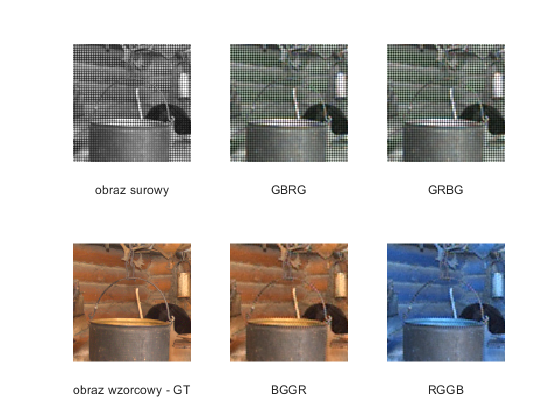

figure(1);
subtitle('Identyfikacja układumatrycy Bayera');
subplot (2,3,1);
imshow(I(80:180,90:190));
xlabel('obraz surowy');
subplot (2,3,2);
imshow(obraz1(80:180,90:190,:));
xlabel('GBRG');
subplot (2,3,3);
imshow(obraz3(80:180,90:190,:));
xlabel('GRBG');
subplot (2,3,4);
imshow(IGT(80:180,90:190,:));
xlabel('obraz wzorcowy - GT')
subplot (2,3,5);
imshow(obraz2(80:180,90:190,:));
xlabel('BGGR')
subplot (2,3,6);
imshow(obraz4(80:180,90:190,:));
xlabel('RGGB')

Obraz2

obraz2CFA = imread("IMG_7116_srgb_CFA.png");
[obraz1,obraz2,obraz3,obraz4] =zad11(obraz2CFA);
I = imread('IMG_7116_srgb_CFA.png');
IGT=imread('IMG_7116_srgb.png');
PSNRzad1obraz2=psnr(obraz2,IGT)

PSNRzad1obraz2 = 35.3266

figure(2);
title('Identyfikacja układumatrycy Bayera');
subplot (2,3,1);
imshow(I(80:180,1:101));
xlabel('obraz surowy');
subplot (2,3,2);
imshow(obraz1(80:180,1:101,:));
xlabel('GBRG');
subplot (2,3,3);
imshow(obraz3(80:180,1:101,:));
xlabel('GRBG');
subplot (2,3,4);
imshow(IGT(80:180,1:101,:));
xlabel('obraz wzorcowy - GT')
subplot (2,3,5);
imshow(obraz2(80:180,1:101,:));
xlabel('BGGR')
subplot (2,3,6);
imshow(obraz4(80:180,1:101,:));
xlabel('RGGB')



Zad2  obraz 1

obraz21CFA = imread("IMG_012_srgb_CFA.png");
obraz21=zad2(obraz21CFA);

Elapsed time is 0.037402 seconds.


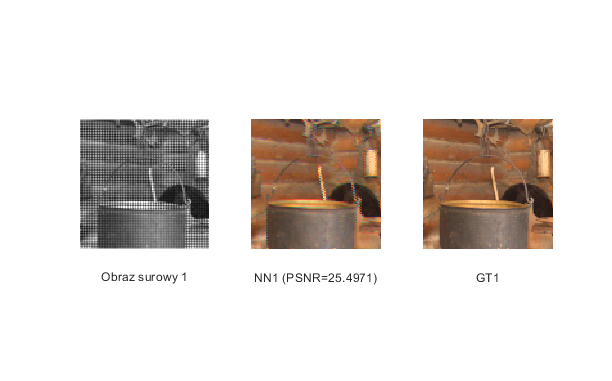

obraz21=obraz21(2:287,2:431,:);
I = imread('IMG_012_srgb_CFA.png');
IGT=imread('IMG_012_srgb.png');
IGT=IGT(2:287,2:431,:);
PSNR1=psnr(obraz21,IGT);
figure(3);
title('Interpolacja metodą najbliższego sąsiada');
subplot (1,3,1);
imshow(I(80:180,90:190));
xlabel('Obraz surowy 1');
subplot (1,3,2);
imshow(obraz21(80:180,90:190,:));
xlabel('NN1 (PSNR=25.4971)');
subplot (1,3,3);
imshow(IGT(80:180,90:190,:));
xlabel('GT1');

Zad2 obraz2

obraz22CFA = imread("IMG_7116_srgb_CFA.png");
obraz22=zad2(obraz22CFA);

Elapsed time is 0.025215 seconds.


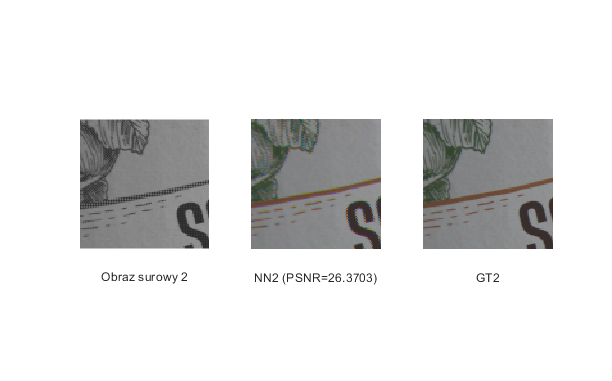

obraz22=obraz22(2:287,2:431,:);
I = imread('IMG_7116_srgb_CFA.png');
IGT2=imread('IMG_7116_srgb.png');
IGT2=IGT2(2:287,2:431,:);
PSNR2=psnr(obraz22,IGT2);
figure(4);
title('Interpolacja metodą najbliższego sąsiada');
subplot (1,3,1);
imshow(I(80:180,1:101));
xlabel('Obraz surowy 2');
subplot (1,3,2);
imshow(obraz22(80:180,1:101,:));
xlabel('NN2 (PSNR=26.3703)');
subplot (1,3,3);
imshow(IGT2(80:180,1:101,:));
xlabel('GT2');

Zad3 obraz 1

obraz31CFA = imread("IMG_012_srgb_CFA.png");
obraz31=zad3(obraz31CFA);

Elapsed time is 0.029828 seconds.


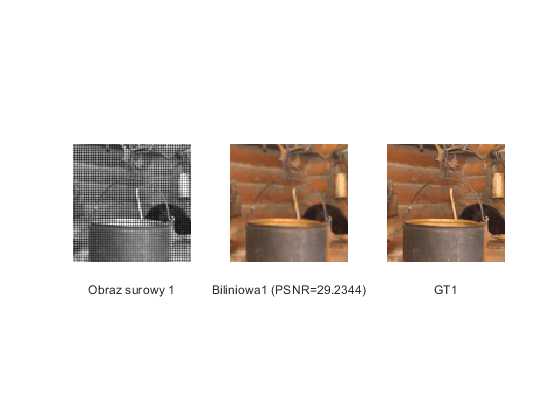

I = imread('IMG_012_srgb_CFA.png');
IGT=imread('IMG_012_srgb.png');
PSNR3=psnr(obraz31,IGT);
figure(5);
title('Interpolacja metodą biliniową');
subplot (1,3,1);
imshow(I(80:180,90:190));
xlabel('Obraz surowy 1');
subplot (1,3,2);
imshow(obraz31(80:180,90:190,:));
xlabel('Biliniowa1 (PSNR=29.2344)');
subplot (1,3,3);
imshow(IGT(80:180,90:190,:));
xlabel('GT1');

Zad3 obraz 2

obraz32CFA = imread("IMG_7116_srgb_CFA.png");
obraz32=zad3(obraz32CFA);

Elapsed time is 0.030659 seconds.


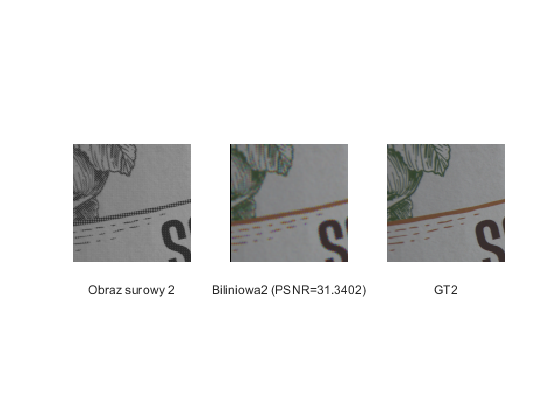

I = imread('IMG_7116_srgb_CFA.png');
IGT2=imread('IMG_7116_srgb.png');
PSNR4=psnr(obraz32,IGT2);
figure(6);
subtitle('Interpolacja metodą biliniową');
subplot (1,3,1);
imshow(I(80:180,1:101));
xlabel('Obraz surowy 2');
subplot (1,3,2);
imshow(obraz32(80:180,1:101,:));
xlabel('Biliniowa2 (PSNR=31.3402)');
subplot (1,3,3);
imshow(IGT2(80:180,1:101,:));
xlabel('GT2');

porownanie 

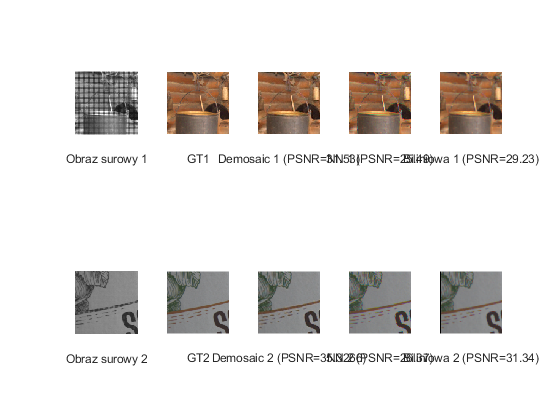

%PORÓWNANIE METOD
close all
clear all
I1 = imread('IMG_012_srgb_CFA.png');
IGT1=imread('IMG_012_srgb.png');
I2=imread('IMG_7116_srgb_CFA.png');
IGT2=imread('IMG_7116_srgb.png');
[obraz1a,obraz2a,obraz3a,obraz4a] =zad11(I1);
[obraz1,obraz2,obraz3,obraz4] =zad11(I2);
obraz21=zad2(I1);
obraz22=zad2(I2);
obraz31=zad3(I1);
obraz32=zad3(I2);
figure(1);
subtitle('Porównanie metod Interpolacji');
subplot (2,5,1);
imshow(I1(80:180,90:190));
xlabel('Obraz surowy 1');
subplot (2,5,2);
imshow(IGT1(80:180,90:190,:));
xlabel('GT1');
subplot (2,5,3);
imshow(obraz2a(80:180,90:190,:));
xlabel('Demosaic 1 (PSNR=31.53)')
subplot (2,5,4);
imshow(obraz21(80:180,90:190,:));
xlabel('NN 1 (PSNR=25.49)')
subplot (2,5,5);
imshow(obraz31(80:180,90:190,:));
xlabel('Biliniowa 1 (PSNR=29.23)')
subplot (2,5,6);
imshow(I2(80:180,1:101,:));
xlabel('Obraz surowy 2')
subplot (2,5,7);
imshow(IGT2(80:180,1:101,:));
xlabel('GT2');
subplot (2,5,8);
imshow(obraz2(80:180,1:101,:));
xlabel('Demosaic 2 (PSNR=35.3266)');
subplot(2,5,9);
imshow(obraz22(80:180,1:101,:));
xlabel('NN 2 (PSNR=26.37)');
subplot (2,5,10);
imshow(obraz32(80:180,1:101,:));
xlabel('Biliniowa 2 (PSNR=31.34)')